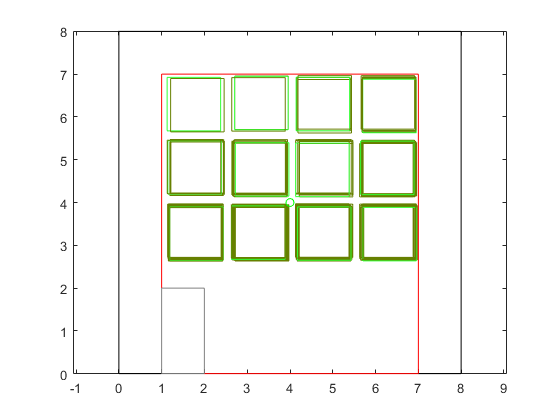

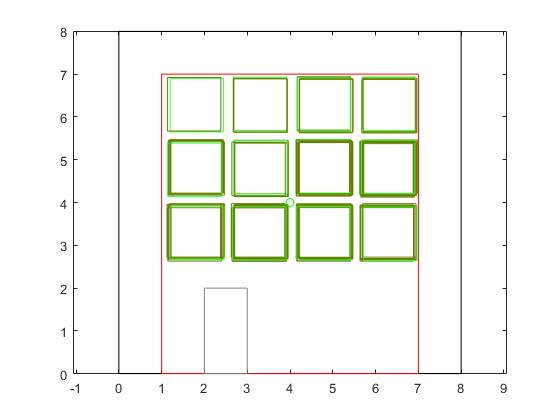

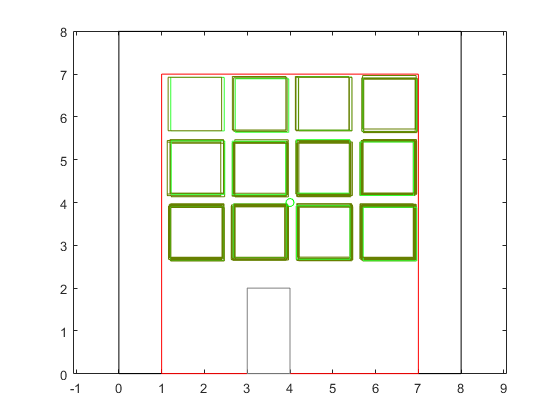

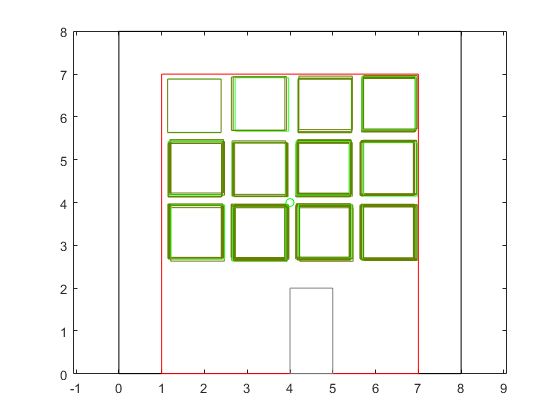

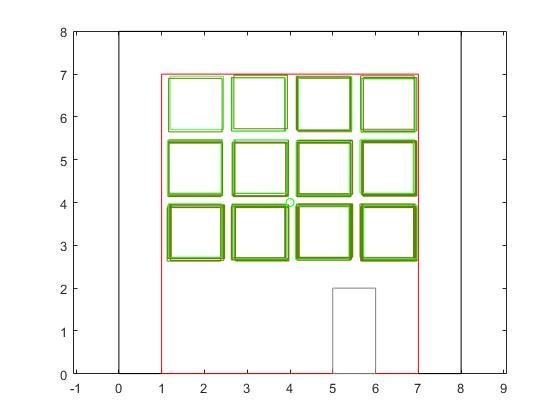

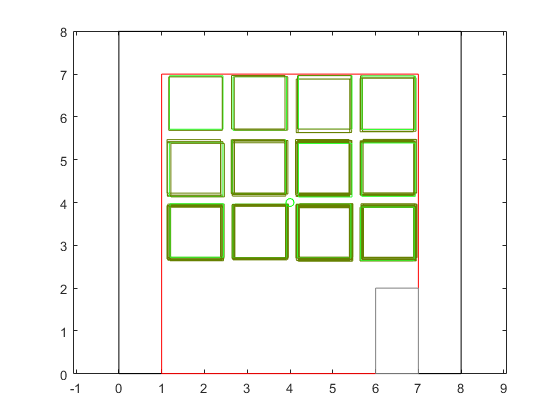

%Dimensions of the House
xStart = 0;
yStart = 0;
height = 8;
width = 8;
doorX = 1;
doorY = 2;
windW = 1.25;
windH = 1.25;
margin = 1;
windMargin = 0.125;
doorStep = 1;
data = 0;

%Find all possible configurations
for door = margin:doorStep:(width-margin-doorX)
    name = num2str(door);
    figure('Name',name);
    plotSquare(xStart, yStart, width, height,[0 0 0]);
    hold on
    %%%Margin
    plotSquare(1,0,6,7,'r');
    grey = [0.5 0.5 0.5]; %color
    plotSquare(door,yStart, doorX, doorY, grey);
    
    for wind1 = 0:11 %possible Locations THIS IS BAD CODE ESPECIALLY WITH MOD
        colW1 = mod(wind1,4); %Value from 0 to 2
        rowW1 = floor(wind1/4); %Value from 0 to 2
        windX = margin + colW1*(2* windMargin + windW) + windMargin + 0.1 * rand();
        windY = height - margin - (rowW1+1)*(2*windMargin + windW) + windMargin + 0.1 * rand();
        plotSquare(windX, windY, windW, windH, [0.2 1 0.2]);

        for wind2 = wind1:11
            colW2 = mod(wind2,4);
            rowW2 = floor(wind2/4);
            windX = margin + colW2*(2* windMargin + windW) + windMargin + 0.1 * rand();
            windY = height - margin - (rowW2+1)*(2*windMargin + windW) + windMargin + 0.1 * rand();
            plotSquare(windX, windY, windW, windH, [0.4 0.5 0]);  
            data = data + 1;
        end
    end
    axis equal;
    plot(4,4,'go')
end

data

data = 468